# HW 3 Deeper Basics V2

## Problem 1 - Conical & Cylindrical Tank

The given figure shows a cylindrical tank with a conical base. If the liquid level is quite low, in the conical part, the volume is simply the conical volume of liquid. If the liquid level is midrange in the cylindrical part, the total volume of liquid includes the filled conical part and the partially filled cylindrical part.

Using M-file, find the volume of the liquid filled in the tank for the following data.

Note that the tank's radius is *R* and the depth of the liquid in the tank is *d*. (Round the final answers to four decimal places.)

d = fluid height

R = height of cone

2R = length of cylinder

% V = V(R, d)
% if elseif based on d & R
% Find volume of cylinder(partial) and volume of 
% cone(full or partial)

R = [0.8 1.5 1.3 1.3];
d = [1 1.25 3.8 4.5];
vol = volConeCyl_v2(R,d)

idx_1 = 1×4 logical array
   0   1   0   0


vol =        NaN    2.0453       NaN       NaN


vol =     0.9383    2.0453   15.5739   -1.0000


% Note: vol(2) is off from ans: they kept R = 1.5 and not d.

Their solution (not vectors), just call 4x

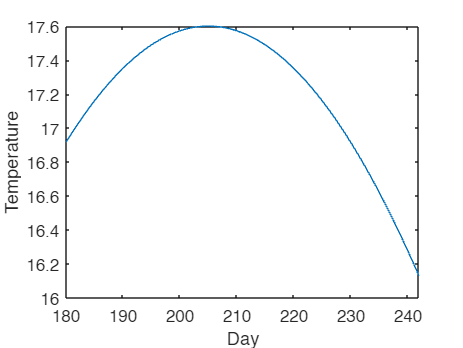

tempAvg = 17.1999

%function Vol = volumeofliquid(R, d)
if d < R
  Vol = pi * d ^ 3 / 3;
elseif d <= 3 * R

  V1 = pi * R ^ 3 / 3;
  V2 = pi * R ^ 2 * (d - R);
  Vol = V1 + V2;
else
  Vol = 'overtop';
end

## Problem 2 - Mean Temp

The average daily temperature for an area can be approximated by the following function:

*T* = *T*mean + (*T*peak − *T*mean) cos(*ω*(*t* − *t*peak))

where *T*mean = the average annual temperature, *T*peak = the peak temperature, *ω* = the frequency of the annual variation (= 2*π*/365), and *t*peak = day of the peak temperature (∼= 205 d). Parameters for some U.S. towns are listed here:

Find the average temperature for July–August in Seattle, WA (*t* = 180 to 242) using the M-file. (Round the final answer to four decimal places.)

% T = T(city, t);
% Switch off of city
city = 'Seattle';
t = 180:242;
tempAvg = cityTempAvg(city, t)

Their solution (less robust in some ways, more in others)

%function Ta = avgtemp(Tm, Tp, ts, te)

r =     2.0000    2.2361    3.0000    3.1623    2.0000    2.2361         0    2.0000    2.8284


th =          0   26.5651   90.0000  161.5651  180.0000 -116.5651         0  -90.0000   45.0000


w = 2*pi/365;
t = ts:te;

r =     2.0000    2.2361    3.0000    3.1623    2.0000    2.2361         0    2.0000    2.8284


T = Tm + (Tp-Tm)*cos(w*(t-205));

th =          0   26.5651   90.0000  161.5651  180.0000 -116.5651         0  -90.0000   45.0000


Ta = mean(T);

## Problem 3 - Cartesian to Polar

Two distances are required to specify the location of a point relative to an origin in two-dimensional space (see figure):

- The horizontal and vertical distances (*x*, *y*) in Cartesian coordinates.

- The radius and angle (*r*, *θ*) in polar coordinates.

It is relatively straightforward to compute Cartesian coordinates (*x*, *y*) on the basis of polar coordinates (*r*, *θ*). The reverse process is not so simple. The radius can be computed by the following formula:

r=√(x2+y2)

If the coordinates lie within the first and fourth coordinates (i.e., *x* > 0), then a simple formula can be used to compute *θ*:

θ=tan−1(y/x)

The difficulty arises for the other cases. The following table summarizes the possibilities:

Using M-file, evaluate the following cases. (Round the final answer to four decimal places. Include a minus sign if necessary). [table having issues]

% If elseif for x and y, evaluate
%       Actually, would only work if it's scalars
%       Better to do vectorized version
% [r,th] = cart2polar(x,y)
x = [2 2 0 -3 -2 -1 0 0 2];
y = [0 1 3 1 0 -2 0 -2 2];

[r,th] = cart2polar(x,y)

r = sqrt(x.^2+y.^2)

U =     0.3523    0.6094    2.7569    1.5894    1.2207


th = rad2deg(atan2(y, x)) %check (matlab default)

Their solution

%function polar2(x, y)
r = sqrt(x .^ 2 + y .^ 2);
n = length(x);
for i = 1:n
   if x(i) > 0
     th(i) = atan(y(i) / x(i));
   elseif x(i) < 0
     if y(i) > 0
       th(i) = atan(y(i) / x(i)) + pi;
     elseif y(i) < 0
       th(i) = atan(y(i) / x(i)) - pi;
     else
       th(i) = pi;
     end
   else
     if y(i) > 0

tt =          0    2.5000    5.0000    7.5000   10.0000   12.5000   15.0000   17.5000   20.0000


       th(i) = pi / 2;

yy =    18.0000   16.2426   12.0000    7.7574    6.0000    7.7574   12.0000   16.2426   18.0000


     elseif y(i) < 0
       th(i) = -pi / 2;
     else
       th(i) = 0;
     end
   end
   th(i) = th(i) * 180 / pi;
end
ou=[x;y;r;th];
fprintf('\n    x     y    radius    angle\n');
fprintf('%8.2f %8.2f %10.4f %10.4f\n',ou);

## Problem 4 - Flow Velo in Channels

Manning’s equation can be used to compute the velocity of water in a rectangular open channel:

U=S√n(BHB+2H)2/3

where *U* = velocity (m/s), *S* = channel slope, *n* = roughness coefficient, *B* = width (m), and *H* = depth (m). The following data are available for five channels:

Using M-file, find the velocity for all five channels. (Round the final answers to four decimal places.)

n = [0.036 0.020 0.015 0.030 0.022];
S = [0.0001 0.0002 0.0012 0.0007 0.0003];
B = [10 8 20 25 15];
H = [2 1 1.5 3 2.6];

U = chanFlowVelo(n,S,B,H)

Their solution

%function Manning(A)
A(:,5)=sqrt(A(:,2))./A(:,1).*(A(:,3).*A(:,4)./(A(:,3)+2*A(:,4))).^(2/3);
fprintf('\n  n    S     B     H     U\n');
fprintf('%8.3f %8.4f %10.2f %10.2f %10.4f\n',A');

## Problem 5 - Vectorization

Identify the vectorized version of the following code:

tstart=0; tend=20; ni=8;
t(1)=tstart;
y(1)=12 + 6*cos(2*pi*t(1)/(tend-tstart));
for i=2:ni+1
    t(i)=t(i-1)+(tend-tstart)/ni;
    y(i)=12 + 6*cos(2*pi*t(i)/(tend-tstart));
end

Vectorized version:

% eliminate the for loop
tstart=0; tend=20; ni=8;
t = tstart:((tend-tstart)/ni):tend;
y = 12 + 6*cos(2*pi*t/(tend-tstart));

% Answer version
tt=tstart:(tend-tstart)/ni:tend;
yy=12+6*cos(2*pi*tt/(tend-tstart));